# Flux balance analysis models for iMAT

*Created by Michiel Adriaens (MaCSBio, Maastricht University, 26-06-2020)*

*Adapted by Catarina and Likhitha*

## **Section 0: Intialisation**

% Start the COBRA toolbox. We will additionally turn all warnings of for the time being
cd C:\Users\likhitha\Desktop\cobratoolbox;
warning('off','all');
initCobraToolbox(false);



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2021
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.30.0).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu


% There are different solvers available to perform flux balance analysis. Simply stick to the default
changeCobraSolver('glpk','all');

 > The solver compatibility is not tested with MATLAB R2020b.
 > changeCobraSolver: Solver for LP problems has been set to glpk.
 > The solver compatibility is not tested with MATLAB R2020b.
 > changeCobraSolver: Solver for MILP problems has been set to glpk.
 > changeCobraSolver: Solver glpk not supported for problems of type MIQP. Currently used: gurobi 
 > changeCobraSolver: Solver glpk not supported for problems of type NLP. No solver set for this problemtype 
 > changeCobraSolver: Solver glpk not supported for problems of type QP. Currently used: gurobi 



% Load the rat model
cd 'C:\Users\likhitha\Desktop\Project_arrhthymia_scripts\Project_arrhthymia\Data\iRno';
iRnoModel = readCbModel('iRnomodel.mat');

Each model.subSystems{x} has been changed to a character array.



model = iRnoModel;

%RPMImediumSimulation;
%modelRPMI;

## Section 1: Perfom flux balance analysis (FBA) simulating aerobic conditions

% Import the gene expression data
cd 'C:\Users\likhitha\Desktop\Project_arrhthymia_scripts\Project_arrhthymia\Data\RNAseqdata';
gxData = readtable('CardioGEM_Rat_geneExpressionData.txt'); 

## Section 2: Simulate ATP production in cancer cells under aerobic conditions

Let's perform the flux balance analysis for an aerobic model for: inhibitor, precursor, scramble inhibitor and scramble precursor

% Load models
cd 'C:\Users\likhitha\Desktop\Project_arrhthymia_scripts\Project_arrhthymia\Data\iRno';
load('iMAT_model_Inhi_likhitha.mat');
load('iMAT_model_Prec_likhitha.mat');
load('iMAT_model_ScrInhi_likhitha.mat');
load('iMAT_model_ScrPrec_likhitha.mat');

% Assign models to correct variable name

% Precursor model
modelaerobiPrec = iMAT_Prec_model;
modelaerobiPrec = changeObjective(modelaerobiPrec, 'RCR11017'); 
modelaerobiPrec = changeRxnBounds(modelaerobiPrec, 'RCR30011', -1000, '1');
FBAaerobicPrec = optimizeCbModel(modelaerobiPrec, 'max');

% Inhibitor model
modelaerobiInhi = iMAT_Inhi_model;
modelaerobiInhi = changeObjective(modelaerobiInhi, 'RCR11017');
modelaerobiInhi = changeRxnBounds(modelaerobiInhi, 'RCR30011', -1000, '1');
FBAaerobicInhi = optimizeCbModel(modelaerobiInhi, 'max');

% Scramble precursor
modelaerobiScrPrec = iMAT_ScrPrec_model;
modelaerobiScrPrec = changeObjective(modelaerobiScrPrec, 'RCR11017'); 
modelaerobiScrPrec = changeRxnBounds(modelaerobiScrPrec, 'RCR30011', -1000, 'l');
FBAaerobicScrPrec = optimizeCbModel(modelaerobiScrPrec, 'max');

% Scramble inhibitor
modelaerobiScrInhi = iMAT_ScrInhi_model;
modelaerobiScrInhi = changeObjective(modelaerobiScrInhi, 'RCR11017'); 
modelaerobiScrInhi = changeRxnBounds(modelaerobiScrInhi, 'RCR30011', -1000, 'l');
FBAaerobicScrInhi = optimizeCbModel(modelaerobiScrInhi, 'max');


## Section 3: Compare results  

Let's visualize the results by focussing on reactions involving lactate in the cytosol.

*IMPORTANT: SELECT THE FOLLOWING CODE AND PRESS F9:*

% Aerobic in Precursor model 
model1 = modelaerobiPrec

model1 = struct with fields:
                      S: [2025×2682 double]
                   mets: {2025×1 cell}
                      b: [2025×1 double]
                 csense: [2025×1 char]
                   rxns: {2682×1 cell}
                     lb: [2682×1 double]
                     ub: [2682×1 double]
                      c: [2682×1 double]
              osenseStr: 'max'
                  genes: {2326×1 cell}
                  rules: {2682×1 cell}
              compNames: {8×1 cell}
                  comps: {8×1 cell}
             metCharges: [2025×1 double]
            metFormulas: {2025×1 cell}
              metSmiles: {2025×1 cell}
               metNames: {2025×1 cell}
         metInChIString: {2025×1 cell}
              metKEGGID: {2025×1 cell}
             metChEBIID: {2025×1 cell}
           metPubChemID: {2025×1 cell}
                grRules: {2682×1 cell}
             rxnGeneMat: [2682×2326 double]
    rxnConfidenceScores: [2682×1 double]
               rxnNames: {2

Start_time = '2021_1_10_22_9_36.006'

Biograph object with 107 nodes and 126 edges.


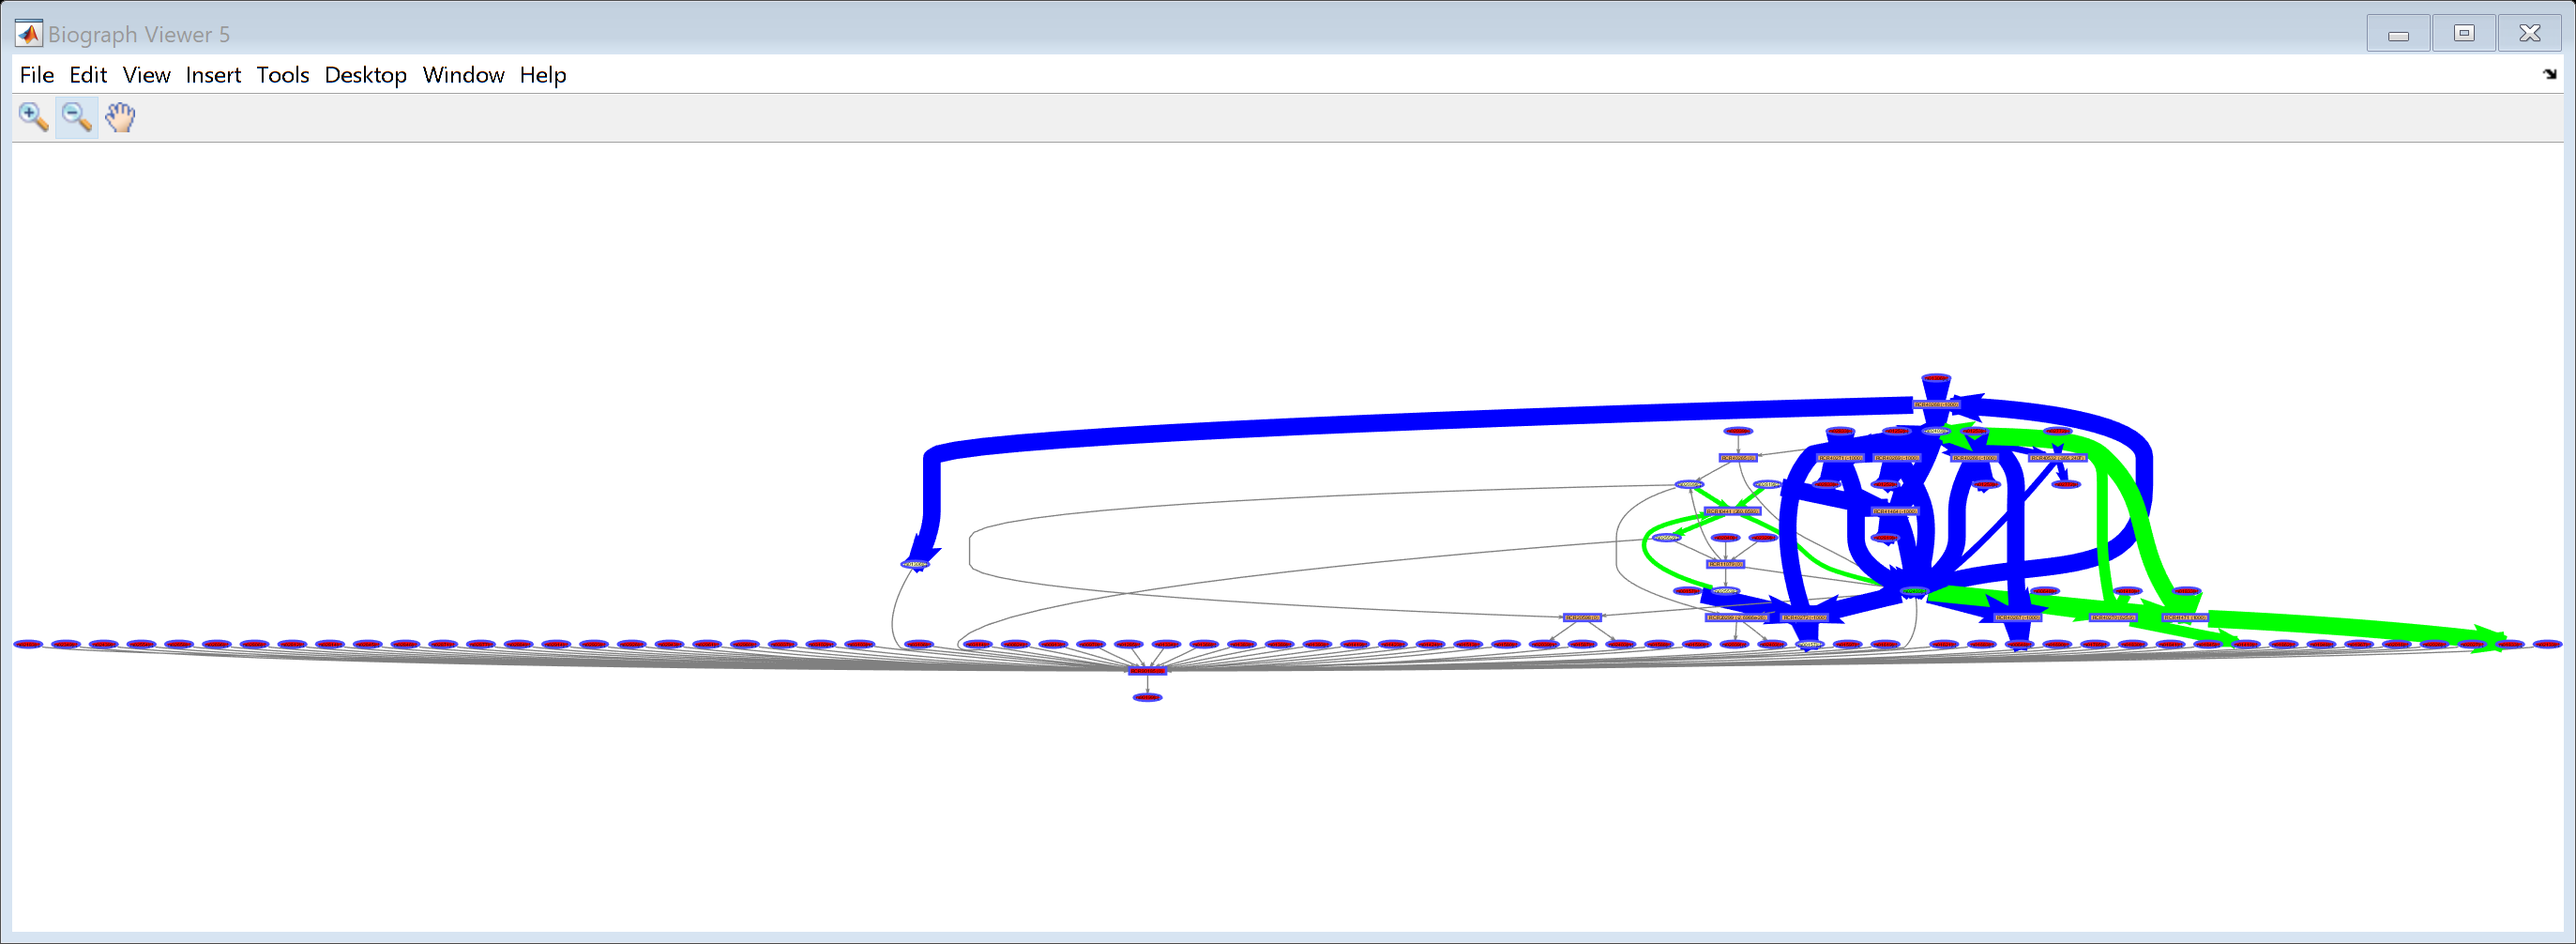

End_time = '2021_1_10_22_9_45.713'

Total_time = '0_0_0_0_0_9.707'

draw_by_met(model1, {'m02403[c]'}, 'true', 1, 'struc', {''}, FBAaerobicPrec.v);


% Aerobic in Inhibitor model
model2 = modelaerobiInhi

model2 = struct with fields:
                      S: [2125×2859 double]
                   mets: {2125×1 cell}
                      b: [2125×1 double]
                 csense: [2125×1 char]
                   rxns: {2859×1 cell}
                     lb: [2859×1 double]
                     ub: [2859×1 double]
                      c: [2859×1 double]
              osenseStr: 'max'
                  genes: {2326×1 cell}
                  rules: {2859×1 cell}
              compNames: {8×1 cell}
                  comps: {8×1 cell}
             metCharges: [2125×1 double]
            metFormulas: {2125×1 cell}
              metSmiles: {2125×1 cell}
               metNames: {2125×1 cell}
         metInChIString: {2125×1 cell}
              metKEGGID: {2125×1 cell}
             metChEBIID: {2125×1 cell}
           metPubChemID: {2125×1 cell}
                grRules: {2859×1 cell}
             rxnGeneMat: [2859×2326 double]
    rxnConfidenceScores: [2859×1 double]
               rxnNames: {2

Start_time = '2021_1_10_22_9_45.764'

Biograph object with 107 nodes and 126 edges.


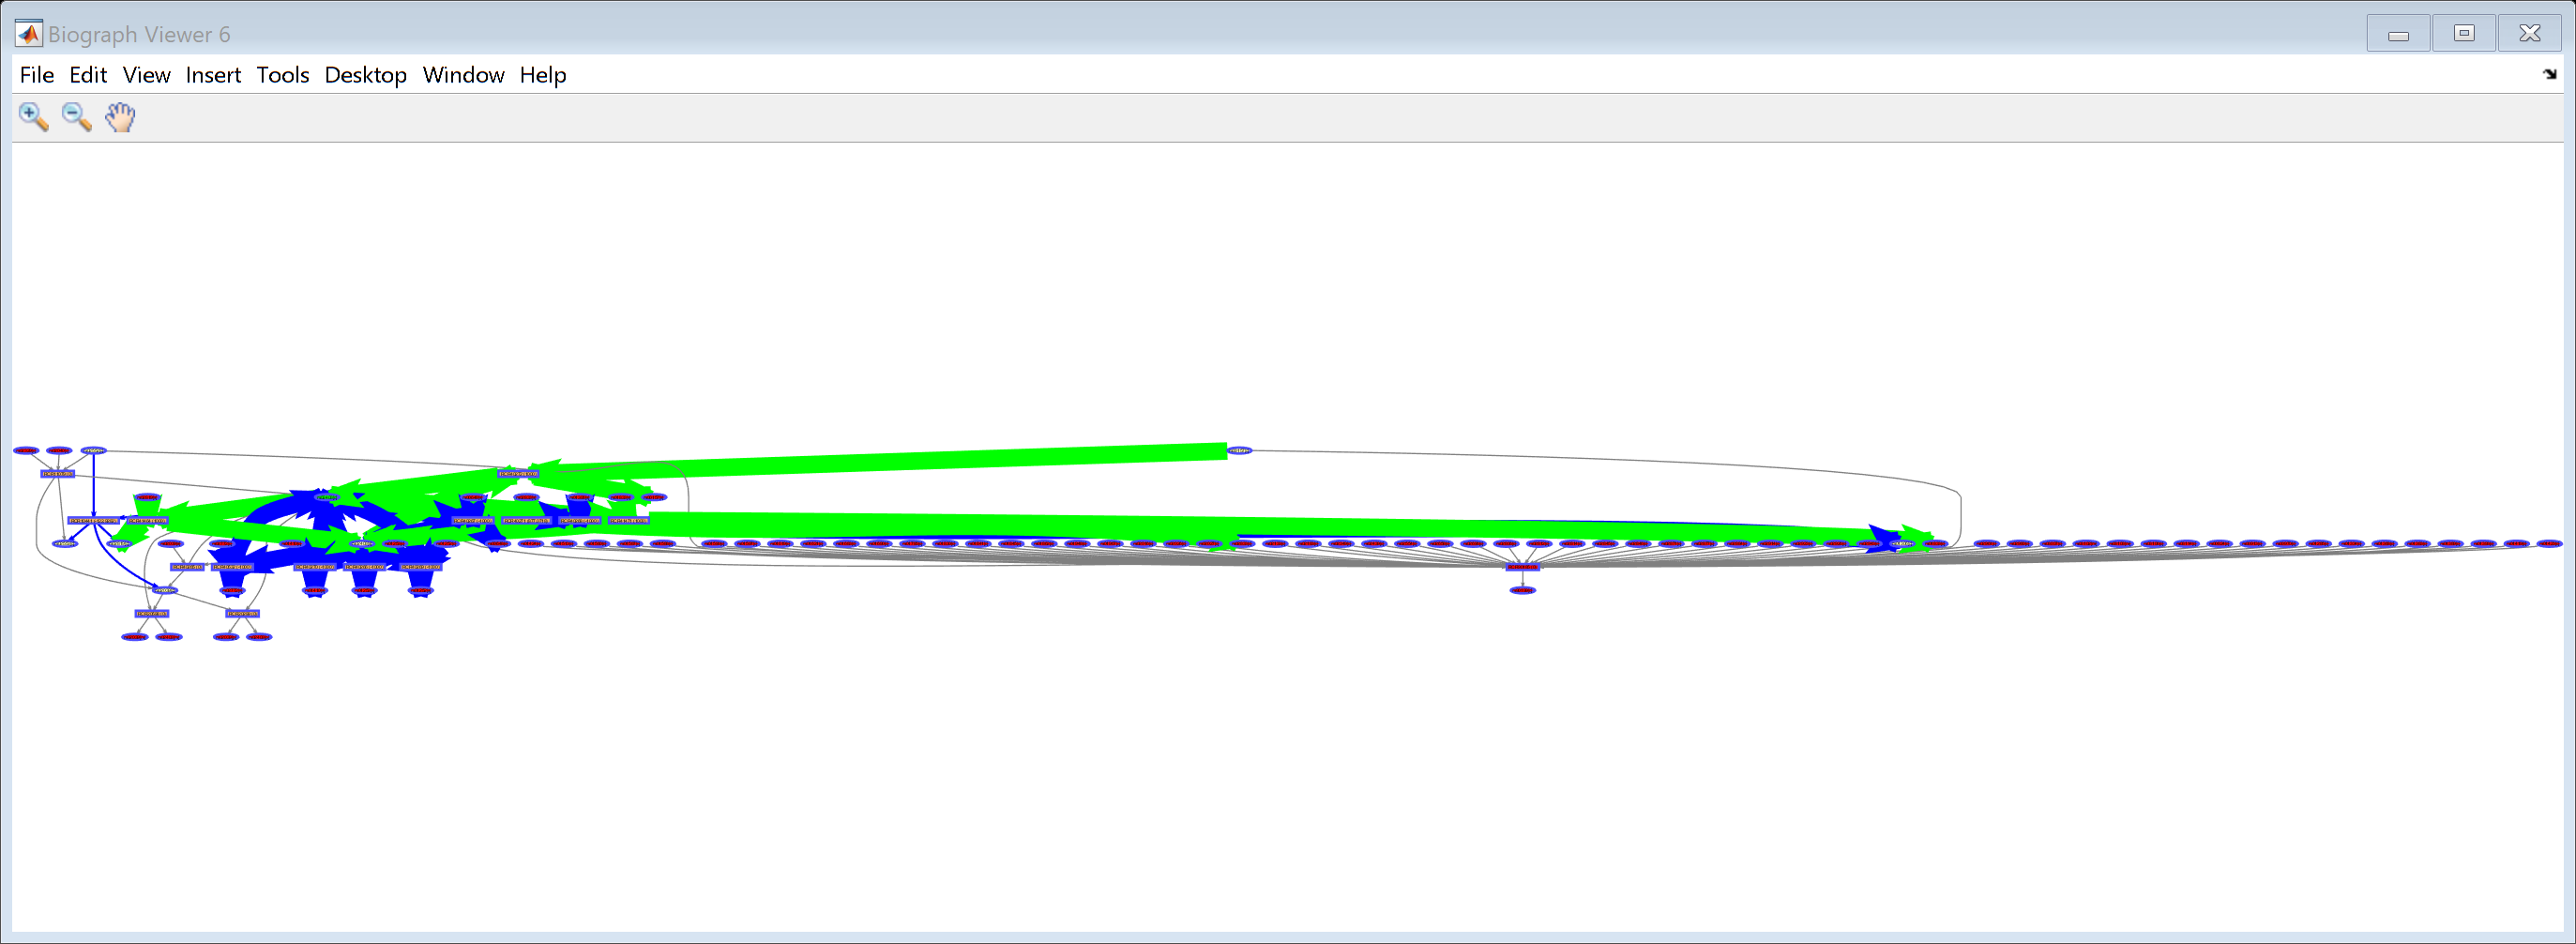

End_time = '2021_1_10_22_9_57.659'

Total_time = '0_0_0_0_0_11.895'

draw_by_met(model2, {'m02403[c]'}, 'true', 1, 'struc', {''}, FBAaerobicInhi.v);


% Aerobic in Scramble Precursor model
model3 = modelaerobiScrPrec

model3 = struct with fields:
                      S: [2210×2988 double]
                   mets: {2210×1 cell}
                      b: [2210×1 double]
                 csense: [2210×1 char]
                   rxns: {2988×1 cell}
                     lb: [2988×1 double]
                     ub: [2988×1 double]
                      c: [2988×1 double]
              osenseStr: 'max'
                  genes: {2326×1 cell}
                  rules: {2988×1 cell}
              compNames: {8×1 cell}
                  comps: {8×1 cell}
             metCharges: [2210×1 double]
            metFormulas: {2210×1 cell}
              metSmiles: {2210×1 cell}
               metNames: {2210×1 cell}
         metInChIString: {2210×1 cell}
              metKEGGID: {2210×1 cell}
             metChEBIID: {2210×1 cell}
           metPubChemID: {2210×1 cell}
                grRules: {2988×1 cell}
             rxnGeneMat: [2988×2326 double]
    rxnConfidenceScores: [2988×1 double]
               rxnNames: {2

Start_time = '2021_1_10_22_9_57.703'

Biograph object with 107 nodes and 126 edges.


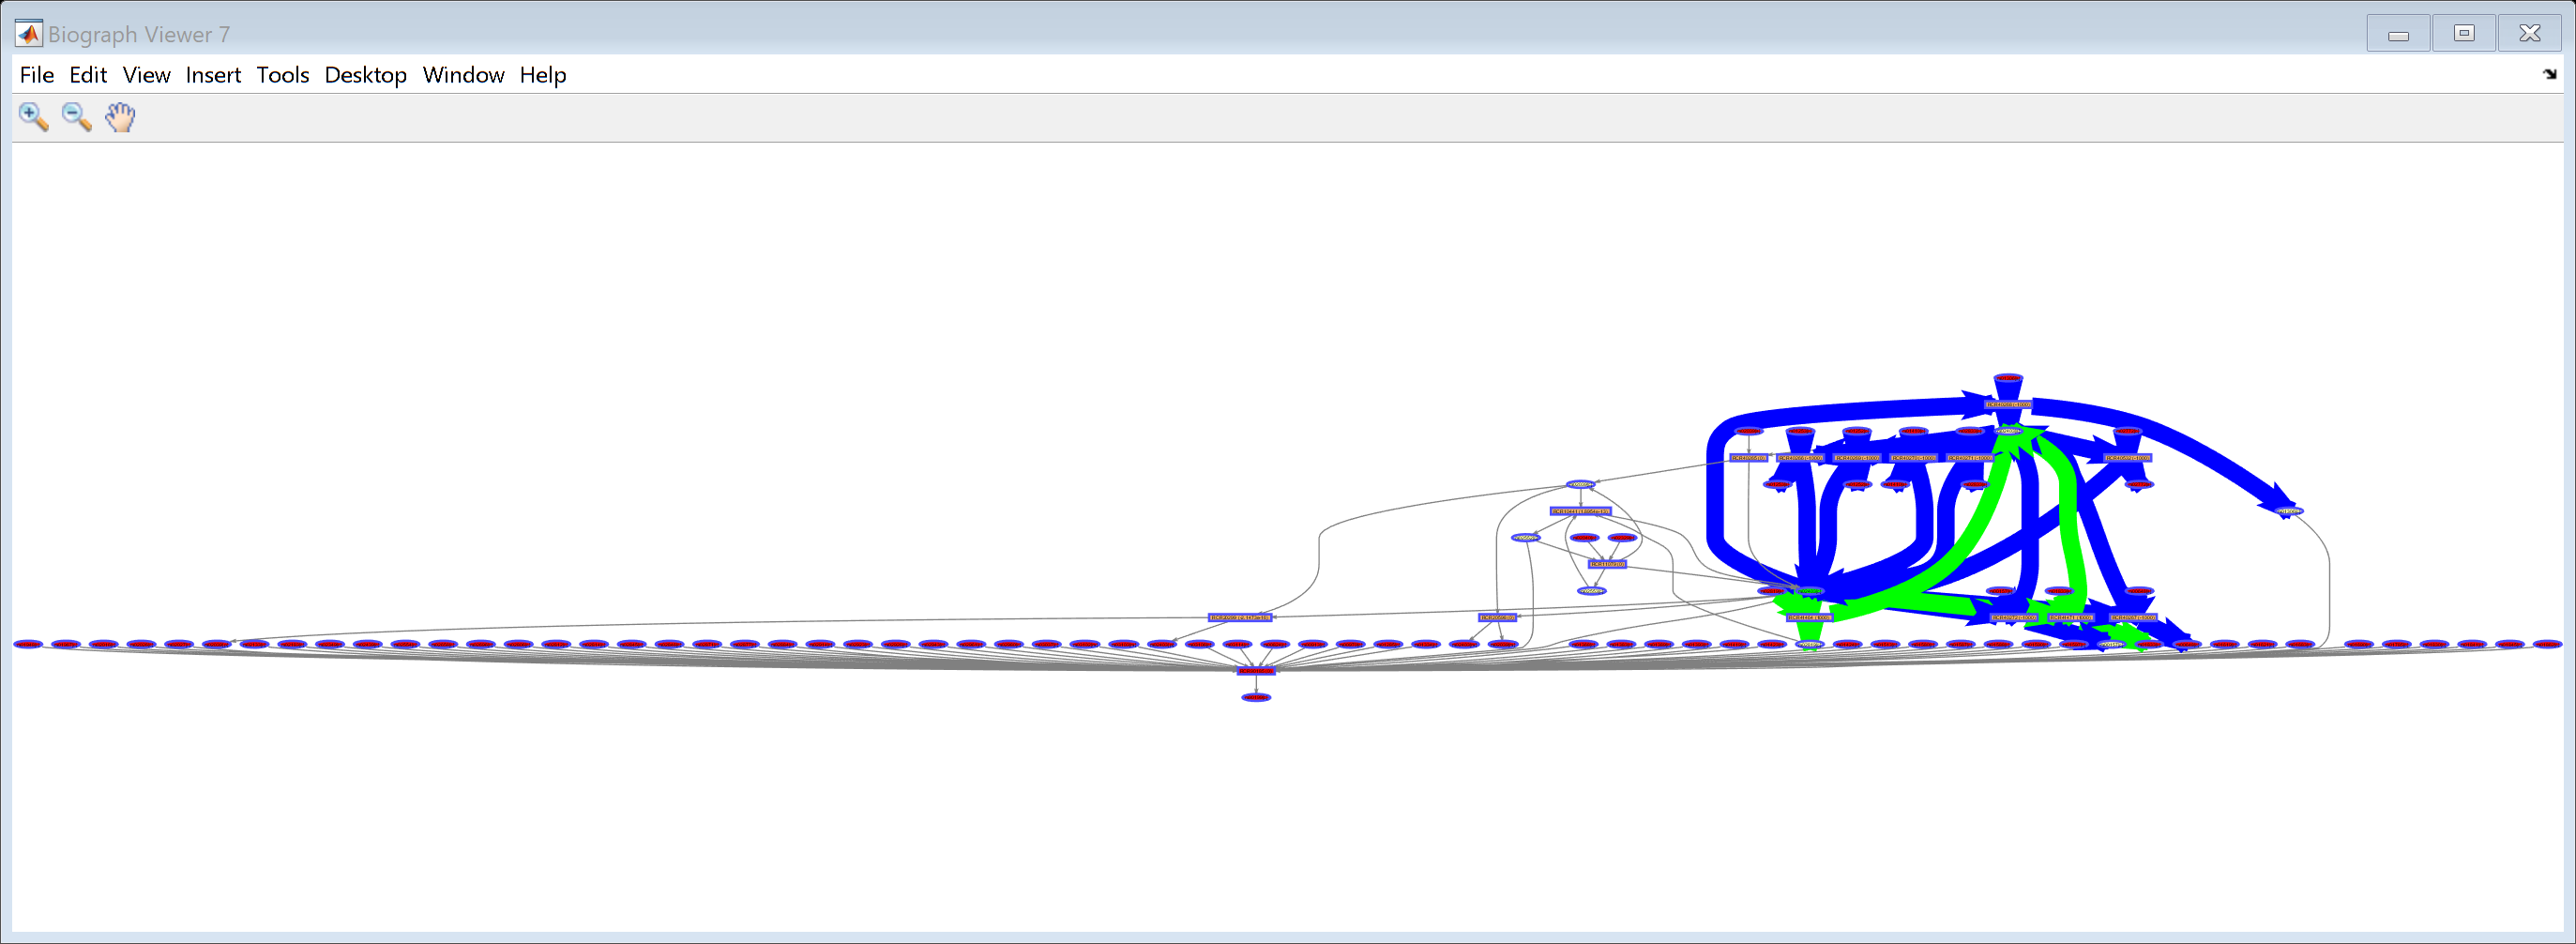

End_time = '2021_1_10_22_10_7.455'

Total_time = '0_0_0_0_1_-50.248'

draw_by_met(model3, {'m02403[c]'}, 'true', 1, 'struc', {''}, FBAaerobicScrPrec.v);


% Aerobic in Scramble Inhibitor model
model4 = modelaerobiScrInhi

model4 = struct with fields:
                      S: [2147×2847 double]
                   mets: {2147×1 cell}
                      b: [2147×1 double]
                 csense: [2147×1 char]
                   rxns: {2847×1 cell}
                     lb: [2847×1 double]
                     ub: [2847×1 double]
                      c: [2847×1 double]
              osenseStr: 'max'
                  genes: {2326×1 cell}
                  rules: {2847×1 cell}
              compNames: {8×1 cell}
                  comps: {8×1 cell}
             metCharges: [2147×1 double]
            metFormulas: {2147×1 cell}
              metSmiles: {2147×1 cell}
               metNames: {2147×1 cell}
         metInChIString: {2147×1 cell}
              metKEGGID: {2147×1 cell}
             metChEBIID: {2147×1 cell}
           metPubChemID: {2147×1 cell}
                grRules: {2847×1 cell}
             rxnGeneMat: [2847×2326 double]
    rxnConfidenceScores: [2847×1 double]
               rxnNames: {2

Start_time = '2021_1_10_22_10_7.504'

Biograph object with 47 nodes and 63 edges.


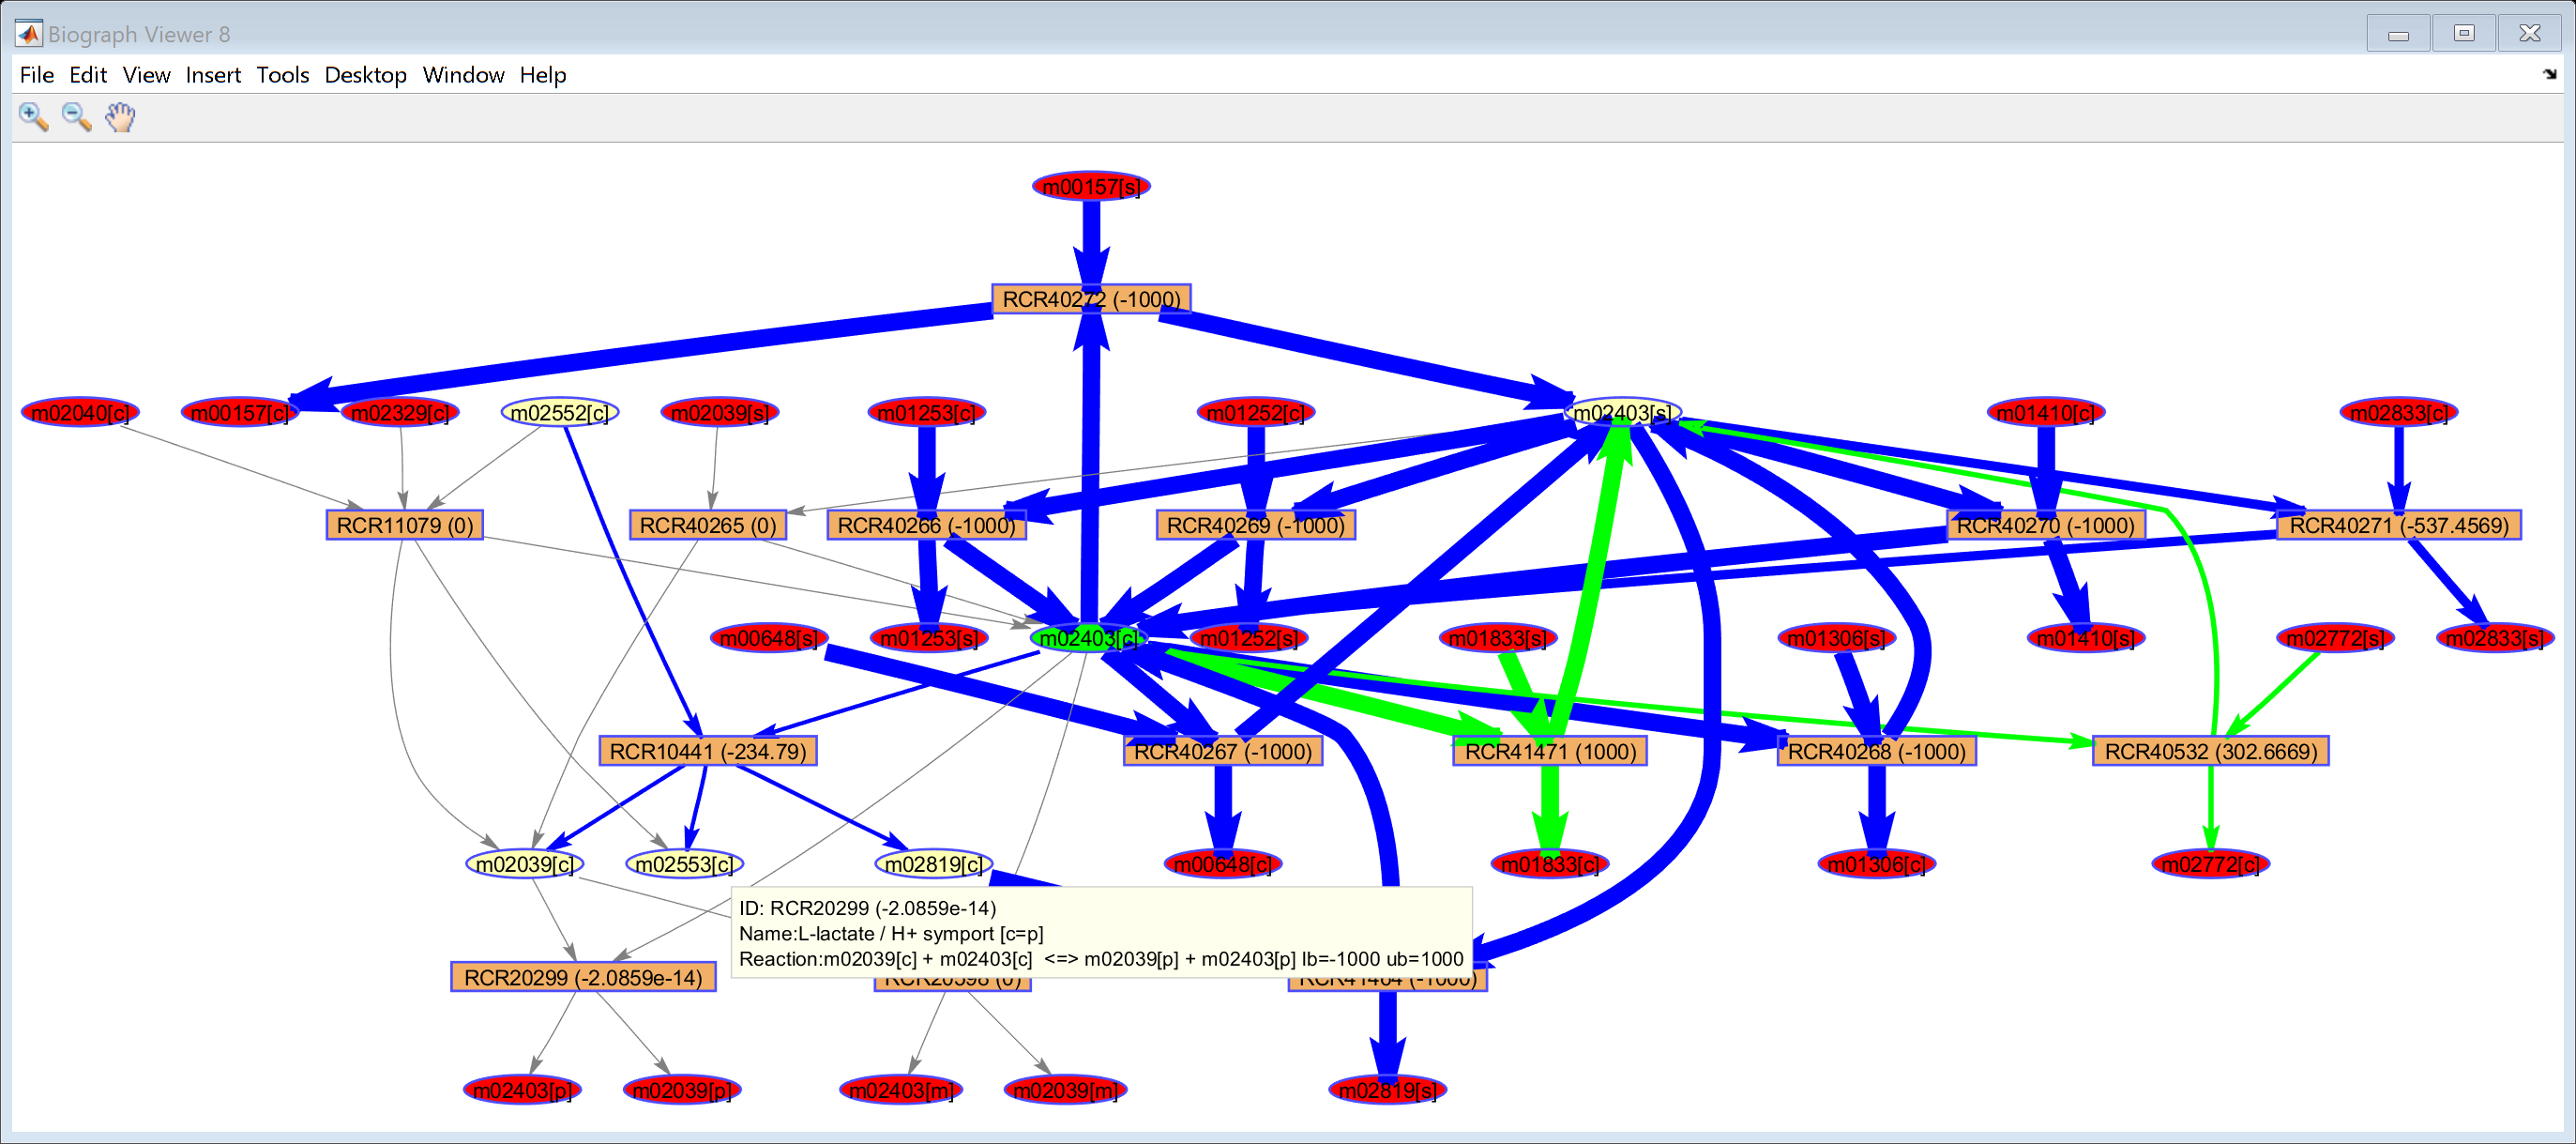

End_time = '2021_1_10_22_10_24.949'

Total_time = '0_0_0_0_0_17.445'

draw_by_met(model4, {'m02403[c]'}, 'true', 1, 'struc', {''}, FBAaerobicScrInhi.v);

*IMPORTANT: SELECT THE FOLLOWING CODE AND PRESS F9:*

% Focus on difference in flux

% Precursor vs Inhibitor
FBAdiffC_Inhi_Prec.v = round(FBAaerobicInhi.v - FBAaerobicPrec.v);

Matrix dimensions must agree.

draw_by_met(model, {'m02403[c]'}, 'true', 1, 'struc', {''}, FBAdiffC_Inhi_Prec.v)
save('FBAdiffC_Inhi_Prec.v', 'Inhi_vs_Prec'); 

% Inhibitor vs Scramble inhibitor
FBAdiffC_Inhi_ScrInhi.v = round(FBAaerobicInhi.v - FBAaerobicScrInhi.v);
draw_by_met(model, {'m02403[c]'}, 'true', 1, 'struc', {''}, FBAdiffC_Inhi_ScrInhi.v)
save('FBAdiffC_Inhi_ScrInhi.v', 'Inhi_vs_ScrInhi');

% Precursor vs Scramble Precursor
FBAdiffC_Prec_ScrPrec.v = round(FBAaerobicPrec.v - FBAaerobicScrPrec.v);
draw_by_met(model, {'m02403[c]'}, 'true', 1, 'struc', {''}, FBAdiffC_Prec_ScrPrec.v)
save('FBAdiffC_Prec_ScrPrec.v', 'Prec_vs_ScrPrec');

% Focus on differences in sign of flux between aerobic and anaerobic

% Precursor vs Inhibitor
FBAdiffSign_Inhi_Prec.v = sign(FBAaerobicPrec.v) - sign(FBAaerobicInhi.v);
draw_by_met(model, {'m02403[c]'}, 'true', 1, 'struc', {''}, FBAdiffSign_Inhi_Prec.v)
save('FBAdiffSign_Inhi_Prec.v', 'Inhi_vs_Prec_sign'); 

% Inhibitor vs Scramble inhibitor
FBAdiffSign_Inhi_ScrInhi.v = sign(FBAaerobicInhi.v) - sign(FBAaerobicScrInhi.v);
draw_by_met(model, {'m02403[c]'}, 'true', 1, 'struc', {''}, FBAdiffSign_Inhi_ScrInhi.v)
save('FBAdiffSign_Inhi_ScrInhi.v', 'Inhi_vs_ScrInhi_sign');

% Precursor vs Scramble Precursor
FBAdiffSign_Prec_ScrPrec.v = round(FBAaerobicPrec.v - FBAaerobicScrPrec.v);
draw_by_met(model, {'m02403[c]'}, 'true', 1, 'struc', {''}, FBAdiffSign_Prec_ScrPrec.v)
save('FBAdiffSign_Prec_ScrPrec.v', 'Prec_vs_ScrPrec_sign');